# **Milano metro stops: solving a travelling salesman problem**

The **travelling salesman problem** is a classic optimization problem in the theory of computational complexity and it asks the following question: "Given a list of cities and the distances between each pair of cities, what is the shortest possible route that visits each city exactly once and returns to the origin city?".

**Why is it difficult:**

- The number of possible routes grows **factorially** with the number of stations.

- TSP is **NP-hard** (belongs to the class of NP-complete problems), meaning there's no known algorithm that solves it efficiently for large inputs.

**Potential applications:**

- On the base level the TSP can be applied to planning and logistics.

- It can be implemented in the manufacture of microchips.

- With some adjustments it can appear in areas such as DNA sequencing.

In this script the travelling salesman problem is beying adapted to the context of the Milano metro system, so in this model the "cities" are **metro stations** and the "salesman" is the **metro train**. The goal is to find the shortes path that visits every metro station once starting from one station and coming back to the same one.

## Development:

#### 1) Environment set up

- **Mapping of the stations.**

The first step is to create a matrix containing the coordinates of all the metro stops. 

The geographical coordinates in degrees are then converted to metric coordinates in kilometres, taking into account that one degree of latitude corresponds to 2π*earth_radius/360 while 1 degree of longitude is 2π*earth_radius*cos(56)/360, where 56 is the aproximate latitude of Milano.

A coordinate system is then fixed and his origin is set at the “depot”. The depot is the designated name of the departure and arrival station and in this scenario it is conventionally located at the Duomo stop.

Another matrix is created containing all distances between the stops and the depot and the mutual distances between the stops.

- **Passenger simulation**

Randomly a number of passengers is generated for each metro station, that number can vary between 5000 and 15000 people for each stop. 

Then are defined:

- The number of daily rides.

- The maximum number of people that can be contained daily in the metro.

- The maximum passengers capacity for a metro line.

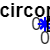

stazioni = [
   -0.00100412529410221000, 0.0029106531254612400000; % Cordusio
   -0.00378174676700382000, 0.0070191622163804400000; % Cairoli
   -0.00377627678319925000, 0.0134305292179615000000; % Cadorna
   -0.00307064518040079000, 0.0229929816359213000000; % Conciliazione
   -0.00384738645259830000, 0.0284761823517208000000; % Pagano
   -0.00611737881219909000, 0.0340373801874403000000; % Bonarotti
   -0.00913113102230056000, 0.0379840367426105000000; % Amendola
   -0.01463313766529950000, 0.0447541907021201000000; % Lotto
   -0.00252602090009901000, -0.0081939792271192900000; % San Babila
   -0.01029082874950400000, -0.0164326386427192000000; % Porta Venezia
   -0.01575044301590370000, -0.0216498855407696000000; % Lima
   -0.00853165845069981000, -0.0134594389526299000000; % Palestro
   -0.00357100437999947000, 0.0339266898190402000000; % Wagner
   -0.01378732725589770000, 0.0325524321035413000000; % Tre Torri
   -0.02061290131999980000, 0.0223642781730611000000; % Geru
   -0.02142691536810300000, -0.0271680104542700000000; % Loreto
   -0.02084502764670050000, -0.0198326397780999000000; % Caiazzo
   -0.02022391485250100000, -0.0134710576509196000000; % Centrale
   -0.02022391484550210000, -0.0059833102913593500000; % Gioia
   -0.01306653883390400000, 0.0045730008837612200000; % Moscova
   -0.00753166412500406000, 0.0065150102399105200000; % Lanza
    0.00257912735689558000, 0.0160277484557305000000; % Sant'Ambrogio
    0.00608260083689771000, 0.0194726838083614000000; % Sant'Agostino
   -0.00215549650530278000, 0.0393475624661406000000; % De Angeli
    0.01169175374690210000, 0.0195488397260206000000; % Porta Genova
    0.00383747882409580000, 0.0011054791463607200000; % Missori
    0.00842003691679594000, -0.0064354380179398900000; % Crocetta
    0.01291909346790020000, -0.0137457722096990000000; % Porta romana
    0.01740053453099930000, -0.0204753789046794000000; % Lodi
   -0.00578515490349929000, -0.0032295558218784500000; % Montenapoleone
   -0.01008821236749920000, -0.0055212233723800400000; % Turati
   -0.01412622704800270000, -0.0078028874706390600000; % Republica
   -0.02519112925430280000, -0.0118537469419895000000; % Sondrio
   -0.02783807256900420000, -0.0032261645612994300000; % Zara
   -0.02313089964999900000, -0.0021415769681585300000; % Isola
   -0.01902919247790180000, 0.0025097335274111300000; % Garibaldi
   -0.02094626671129870000, 0.0082515307668806800000; % Monumentale
   -0.02385393492020430000, 0.0171420845569106000000; % Cenisio
   -0.01697117953629860000, 0.0270915627840616000000; % Domodossola
   -0.01700211515250060000, 0.0387176715228499000000; % Portello
    0.00900624078359868000, 0.0360846991773816000000; % Bolivar
    0.00675284140069721000, 0.0292528630165911000000; % California
    0.00537944161879977000, 0.0244044632148110000000; % Coni Zugna
    0.00503202651550083000, 0.0121802306314009000000; % De Amicis
    0.00737722561199661000, 0.0066044614681999300000; % Vetra
    0.00810748716839527000, 0.0006382883199513860000; % Santa Sofia
    0.00571310721490192000, -0.0049675119601992900000; % Sforza Policlinico
   -0.00349833912780184000, -0.0193824269018492000000; % Tricolore
];

stazioni=[stazioni(:,1)*111.2 stazioni(:,2)*111.2*cosd(56)]; 

rng(1) % For reproducibility
numStazioni(1,:) = size(stazioni,1); 
deposito = [0 0]; % Depot set at Duomo
domanda = 100*randi([50,150],numStazioni,1);
sistema = [deposito;stazioni];

% Graph of the metro stations, indicating the number of users and their location with reference to the depot:

plot(deposito(:,1),deposito(:,2),"+",Color="r")
hold on;
plot(stazioni(:,1),stazioni(:,2),"*",Color="b")
text(sistema(:,1),sistema(:,2),["Depot"; num2str(domanda)]);
title("metro circonvallazione");
xlabel("km");
ylabel("km");


capienzaMetro = 1200; % Setting the maximum metro capacity
numCorseGiornaliere = 25; % Defining the number of daily rides

numSistema = size(sistema,1);
[X, Y] = meshgrid(1:numSistema); % Creating indices to combine al the stops
dist = hypot(sistema(X(:),1) - sistema(Y(:),1), sistema(X(:),2) - sistema(Y(:),2));
dist = reshape(dist, numSistema, numSistema);

capienzaLinea = capienzaMetro * numCorseGiornaliere; % Maximum passengers capacity for each line
customerCoords = sistema(2:end,:);
costMatrix = dist;
vehicleCapacity = capienzaLinea;

#### 2) Clustering.

Metro stops are beying grouped into clusters (i.e. sets of stations), each with a total demand that does not exceed the capacity of the line. 

We start by identifying the furthest stop from the depot which will become the current centre of the cluster; then we will start adding all the nearest stations to the centre one, until the maximum capacity of the metro is reached. 

Once this point is hit, the next closest station will become the current centre of a new cluster. This process is iterated until every station has been put in to a cluster.

clusters = [];
remainingCustomers = 1:size(stazioni,1); % All the available stations
while ~isempty(remainingCustomers)

% We search the furthes stop from the depot (Duomo)
    distsToDepot = hypot(stazioni(remainingCustomers,1), stazioni(remainingCustomers,2));
    [~, idx] = max(distsToDepot);
    startCustomer = remainingCustomers(idx);

% The cluster is beeing initialized

   cluster = struct("Customers", startCustomer, "Center", stazioni(startCustomer,:), "Demand", domanda(startCustomer));

% Stops already visited are removed from the list of remaining customers

   remainingCustomers(idx) = [];

% The process continues by adding new stops to the cluster until the maximum capacity of the metro is reached

   while ~isempty(remainingCustomers)
        distsToCluster = vecnorm(stazioni(remainingCustomers,:) - cluster.Center, 2, 2);
        [~, idx] = min(distsToCluster);
        nextCustomer = remainingCustomers(idx);

% Check to see if a stop can be added without exceeding the capacity limit:

if cluster.Demand + domanda(nextCustomer) > capienzaLinea
            break;
    end

% If so, the cluster stop is added

        cluster = addToCluster(cluster, nextCustomer, stazioni, domanda);
        remainingCustomers(idx) = []; % Rimuovila dalla lista
   end

% The created cluster is saved

clusters = [clusters, cluster];
end

Unrecognized function or variable 'addToCluster'.


% The clusters created are represented in a graph:

plotClusters(clusters, stazioni);

#### 3) Optimization.

After this initial, somewhat crude grouping, an attempt is made to optimise the clusters; if it is found that a stop is closer to another cluster than the one in which it is located and the displacement does not exceed the maximum capacity limits, the stop is relocated.

We then proceed to solve a travelling salesman problem for each cluster in order to find the optimal route of a train starting from the depot seeing all the stops in the cluster and then returning to the starting point.

iterations = 0;

while iterations < 10
    for i = 1:numel(clusters)
        % For each station in the cluster
        for customer = clusters(i).Customers
            % Calculating the distance of the station from the centre of the cluster
            d_i = sqrt(sum((clusters(i).Center - sistema(customer+1,:)).^2));

            % For each alternative cluster
            for j = [1:i-1, i+1:numel(clusters)]
                % Calculating the distance of the station from the centre of the alternative cluster
                d_j = sqrt(sum((clusters(j).Center - sistema(customer+1,:)).^2));

                % Move the station to the nearest cluster if capacity constraints are met
                if d_j < d_i && clusters(j).Demand + domanda(customer) < capienzaLinea
                    % Remove the station from the original cluster
                    clusters(i) = removeFromCluster(clusters(i), ...
                        customer, sistema(2:end,:), domanda);

                    % Add station to the new cluster
                    clusters(j) = addToCluster(clusters(j), ...
                        customer, sistema(2:end,:), domanda);
                    
                    break
                end
            end
        end
    end
    iterations = iterations + 1;
end

% The indices of the stations in the clusters are corrected

nRoutes = numel(clusters);
for i = 1:nRoutes
    clusters(i).Customers = clusters(i).Customers + 1;
end

% Solving the TSP for each cluster

TSPsolutions = cell(numel(clusters),1);
Routes = cell(numel(clusters),1);
customerCoords = sistema; 

for rt = 1:nRoutes
    % Compute pairwise distance
    cluster = clusters(rt);
    coords = [deposito; customerCoords(cluster.Customers,:)];
    M = height(coords);
    [X,Y] = meshgrid(1:M);
    dist = hypot(coords(X(:),1)- coords(Y(:),1),coords(X(:),2) - coords(Y(:),2));
    
    % Collect TSP data
    tsp.CostMatrix = reshape(dist,M,M);
    tsp.Customers = cluster.Customers;
    % Solve this TSP
    TSPsolutions{rt} = solvemyTSP(tsp);
    Routes{rt} = TSPsolutions{rt}.Route;
end

% The optimal path of each claster is represented graphically

plotClusters(clusters,sistema,Routes)